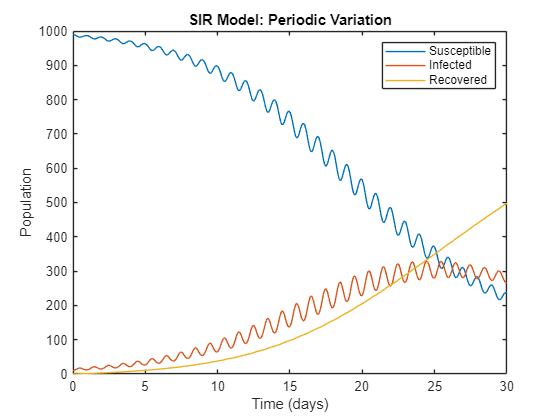

Q4_flag(1) = 1; Q1;
% This runs the script for Q1 without importing any of the plots made in
% the script.

% New Parameters
B0 = 0.3;                       % Initial transmission rate
A = 5;                          % Amplitude
w = (2*pi*365) / 365;           % Angular frequency

% Edited Parameters
T = 30;                         % Total simulation time (days)
h = 0.1;                        % Time step (days)
t_vec = linspace(0,30,30/h+1);  % Time vector for easier plotting

B = @(t) B0*(1 + A*sin(w*t));     % Transmission rate variation
gamma = 0.1;                    % New gamma value

% SIR model with β(t)

% RK4 method
    for t = 1:300
        % Current values
        S_t = S(t); I_t = I(t); R_t = R(t);
        beta = B(t/10);

        % Define ODEs
        dS = @(S, I) -(beta / N) * S * I;
        dI = @(S, I) (beta / N) * S * I - gamma * I;
        dR = @(I) gamma * I;

        % RK4 coefficients
        k1_S = h * dS(S_t, I_t);
        k1_I = h * dI(S_t, I_t);
        k1_R = h * dR(I_t);

        k2_S = h * dS(S_t + k1_S/2, I_t + k1_I/2);
        k2_I = h * dI(S_t + k1_S/2, I_t + k1_I/2);
        k2_R = h * dR(I_t + k1_I/2);

        k3_S = h * dS(S_t + k2_S/2, I_t + k2_I/2);
        k3_I = h * dI(S_t + k2_S/2, I_t + k2_I/2);
        k3_R = h * dR(I_t + k2_I/2);

        k4_S = h * dS(S_t + k3_S, I_t + k3_I);
        k4_I = h * dI(S_t + k3_S, I_t + k3_I);
        k4_R = h * dR(I_t + k3_I);
        
        S(t+1) = S_t + (k1_S + 2*k2_S + 2*k3_S + k4_S) / 6;
        I(t+1) = I_t + (k1_I + 2*k2_I + 2*k3_I + k4_I) / 6;
        R(t+1) = R_t + (k1_R + 2*k2_R + 2*k3_R + k4_R) / 6;
    end
plot(t_vec, S, t_vec, I, t_vec, R)
xlabel('Time (days)'); ylabel('Population');
legend('Susceptible', 'Infected', 'Recovered');
title('SIR Model: Periodic Variation');

The recovery rate doesn't seem to oscilate at all, but the susceptibility and infection rates definitely have some oscilating happening.

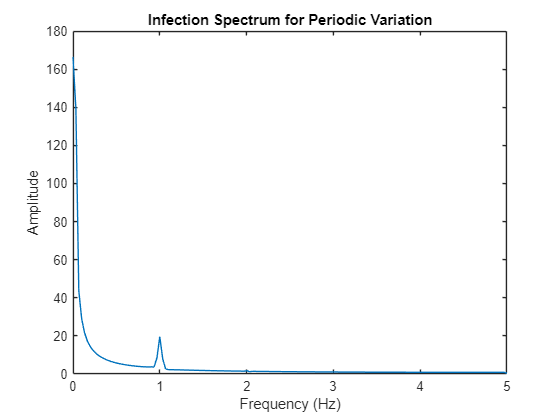


fft_I = fft(I);
Fs = 1/T;
samples = 300;
f_vec = Fs * (0:(samples/2));
P_I = abs(fft_I/samples);
F_I = P_I(1:samples/2+1);
F_I(2:end-1) = 2 * F_I(2:end-1);
plot(f_vec, F_I)
xlabel('Frequency (Hz)'); ylabel('Amplitude');
title('Infection Spectrum for Periodic Variation');

This looks like a logarithmic graph with a blip at 1 Hz. This makes sense.

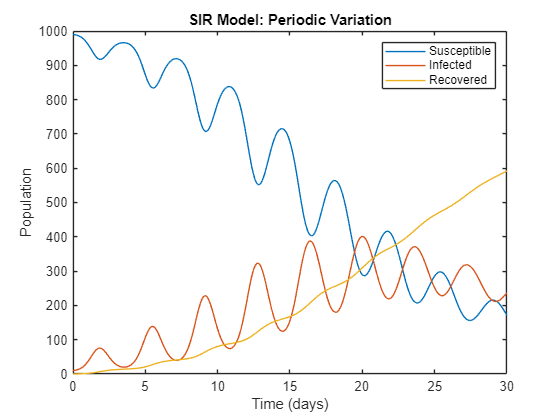


% Edited parameters
w = (2*pi*100) / 365;           % Angular frequency
B = @(t) B0*(1 + A*sin(w*t));     % Transmission rate variation

% RK4 method
    for t = 1:300
        % Current values
        S_t = S(t); I_t = I(t); R_t = R(t);
        beta = B(t/10);

        % Define ODEs
        dS = @(S, I) -(beta / N) * S * I;
        dI = @(S, I) (beta / N) * S * I - gamma * I;
        dR = @(I) gamma * I;

        % RK4 coefficients
        k1_S = h * dS(S_t, I_t);
        k1_I = h * dI(S_t, I_t);
        k1_R = h * dR(I_t);

        k2_S = h * dS(S_t + k1_S/2, I_t + k1_I/2);
        k2_I = h * dI(S_t + k1_S/2, I_t + k1_I/2);
        k2_R = h * dR(I_t + k1_I/2);

        k3_S = h * dS(S_t + k2_S/2, I_t + k2_I/2);
        k3_I = h * dI(S_t + k2_S/2, I_t + k2_I/2);
        k3_R = h * dR(I_t + k2_I/2);

        k4_S = h * dS(S_t + k3_S, I_t + k3_I);
        k4_I = h * dI(S_t + k3_S, I_t + k3_I);
        k4_R = h * dR(I_t + k3_I);
        
        S(t+1) = S_t + (k1_S + 2*k2_S + 2*k3_S + k4_S) / 6;
        I(t+1) = I_t + (k1_I + 2*k2_I + 2*k3_I + k4_I) / 6;
        R(t+1) = R_t + (k1_R + 2*k2_R + 2*k3_R + k4_R) / 6;
    end
plot(t_vec, S, t_vec, I, t_vec, R)
xlabel('Time (days)'); ylabel('Population');
legend('Susceptible', 'Infected', 'Recovered');
title('SIR Model: Periodic Variation');

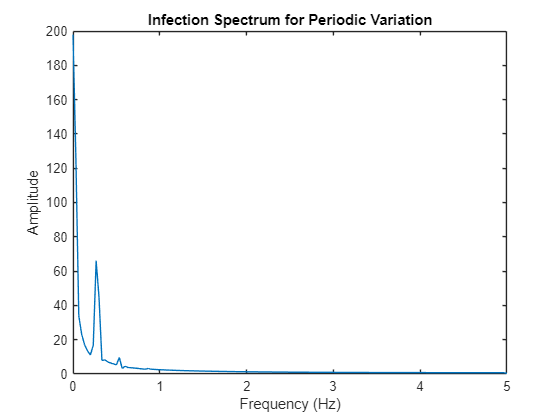


fft_I = fft(I);
Fs = 1/T;
samples = 300;
f_vec = Fs * (0:(samples/2));
P_I = abs(fft_I/samples);
F_I = P_I(1:samples/2+1);
F_I(2:end-1) = 2 * F_I(2:end-1);
plot(f_vec, F_I)
xlabel('Frequency (Hz)'); ylabel('Amplitude');
title('Infection Spectrum for Periodic Variation');

The peak frequency shift to smaller values, but there are now two possible max frequency peaks. This definitely matches what happened to the SIR graph as the wavelengths increased a lot, which does inversely impact frequency, so it makes sense that the peak frequency would decrease. Also, all of the graphs in the SIR now have minor oscilations.